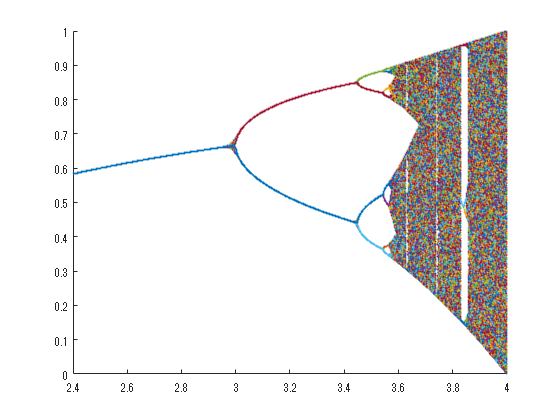

t = 1:500;
a = 2.4:0.001:4.0;
x = ones(size(a)) / 2;

figure
hold on

for i = t
    x = a .* x .* (1 - x);
    if i > 100
        scatter(a, x, 2, 'filled');
    end
end

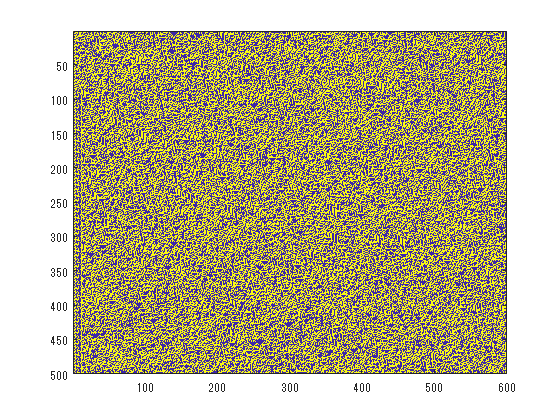

f = 30;

field = zeros(500, 600);    
field(1, :) = int32(randi([0, 1], [1, 600]));

for i = 2:500
    l(2:599) = field(i-1, 1:598);
    s(2:599) = field(i-1, 2:599);
    r(2:599) = field(i-1, 3:600);

    l(1) = field(i - 1, 1);
    s(1) = field(i - 1, 1);
    r(1) = field(i - 1, 2);
    l(599) = field(i - 1, 599);
    s(599) = field(i - 1, 600);
    r(599) = field(i - 1, 600);

    p = l * 4 + s * 2 + r;

    rule = f;
    for j = 0:7
        if rem(rule, 2) == 1
            field(i, p == j) = 1;
        end
        rule = floor(rule / 2);
    end
end

figure
imagesc(field)

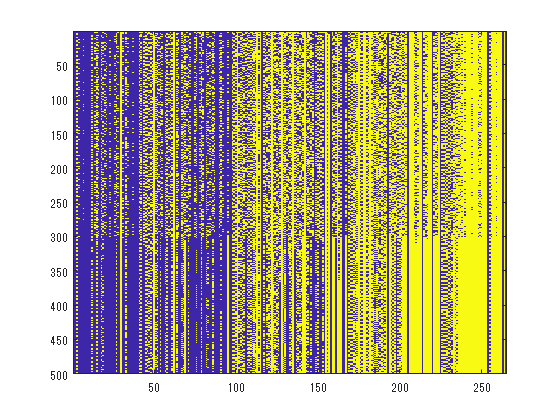

mem = zeros(500, 9, 100);
index = ones(1, 9);

for f = 0:255
    field = zeros(500, 600);    
    field(1, :) = int32(randi([0, 1], [1, 600]));
    count = 0;
    rule = f;
    for j = 0:7
        count = count + rem(rule, 2);
        rule = floor(rule / 2);
    end
    count = int32(count);

    for i = 2:500
        l(2:599) = field(i-1, 1:598);
        s(2:599) = field(i-1, 2:599);
        r(2:599) = field(i-1, 3:600);
    
        l(1) = field(i - 1, 1);
        s(1) = field(i - 1, 1);
        r(1) = field(i - 1, 2);
        l(599) = field(i - 1, 599);
        s(599) = field(i - 1, 600);
        r(599) = field(i - 1, 600);
    
        p = l * 4 + s * 2 + r;
    
        rule = f;
        for j = 0:7
            if rem(rule, 2) == 1
                field(i, p == j) = 1;
            end
            rule = floor(rule / 2);
        end
    end

    mem(:, count + 1, index(1, count + 1)) = field(:, 300);
    index(1, count + 1) = index(1, count + 1) + 1;
end

im = zeros(500, 256);
idx = 1;
for i = 1:9
    im(:, idx:(idx + index(1, i) - 1)) = mem(:, i, 1:index(1, i));
    idx = idx + index(1, i);
end

figure
imagesc(im)

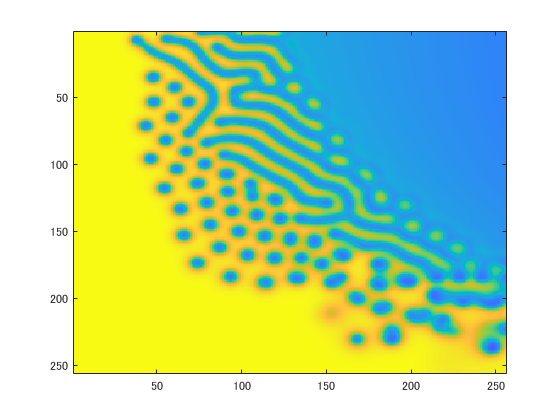

% シミュレーションの各パラメタ
SPACE_GRID_SIZE = 256;
dx = 0.01;
dt = 1;
VISUALIZATION_STEP = 8; % 何ステップごとに画面を更新するか。
FLAME_RATE = 1000;

% モデルの各パラメタ
Du = 2e-5;
Dv = 1e-5;
% f = 0.04; k = 0.06; % amorphous
% f = 0.035; k = 0.065; % spots
% f = 0.012; k = 0.05; % wandering bubbles
% f = 0.02504; k = 0.05; % waves
% f = 0.022; k = 0.051; % stripe

f = 0.05:-0.04/(SPACE_GRID_SIZE-1):0.01;
f = f.' * ones(1, 256);
k = 0.07:-0.02/(SPACE_GRID_SIZE-1):0.05;
k = ones(256, 1) * k;

% 初期化
u = ones(SPACE_GRID_SIZE, SPACE_GRID_SIZE);
v = zeros(SPACE_GRID_SIZE, SPACE_GRID_SIZE);

% 中央にSQUARE_SIZE四方の正方形を置く
SQUARE_SIZE = 20;
SPACE_GRID_SIZE_DIV2 = floor(SPACE_GRID_SIZE / 2);
SQUARE_SIZE_DIV2 = floor(SQUARE_SIZE / 2);
u(SPACE_GRID_SIZE_DIV2 - SQUARE_SIZE_DIV2:SPACE_GRID_SIZE_DIV2 + SQUARE_SIZE_DIV2, SPACE_GRID_SIZE_DIV2 - SQUARE_SIZE_DIV2:SPACE_GRID_SIZE_DIV2 + SQUARE_SIZE_DIV2) = 0.5;
v(SPACE_GRID_SIZE_DIV2 - SQUARE_SIZE_DIV2:SPACE_GRID_SIZE_DIV2 + SQUARE_SIZE_DIV2, SPACE_GRID_SIZE_DIV2 - SQUARE_SIZE_DIV2:SPACE_GRID_SIZE_DIV2 + SQUARE_SIZE_DIV2) = 0.25;

% 対称性を壊すために、少しノイズを入れる
u = u + rand(SPACE_GRID_SIZE, SPACE_GRID_SIZE) * 0.1;
v = v + rand(SPACE_GRID_SIZE, SPACE_GRID_SIZE) * 0.1;

figure
for i = 1:2000

    for t = 1:VISUALIZATION_STEP
        u_pad = padarray(u, [1, 1], 'symmetric');
        v_pad = padarray(v, [1, 1], 'symmetric');
        % ラプラシアンの計算
        laplacian_u = (u_pad(1:end-2, 2:end-1) + u_pad(3:end, 2:end-1) + u_pad(2:end-1, 1:end-2) + u_pad(2:end-1, 3:end) - 4 * u) / (dx * dx);
        laplacian_v = (v_pad(1:end-2, 2:end-1) + v_pad(3:end, 2:end-1) + v_pad(2:end-1, 1:end-2) + v_pad(2:end-1, 3:end) - 4 * v) / (dx * dx);
        % Gray - Scottモデル方程式
        dudt = Du * laplacian_u - u .* v .* v + f .* (1.0 - u);
        dvdt = Dv * laplacian_v + u .* v .* v - (f + k) .* v;
        u = u + dt * dudt;
        v = v + dt * dvdt;
    end

    % 表示をアップデート
    imagesc(u, [0 1])
    pause(1 / FLAME_RATE)
end